# find the area of a shape 

findArea( shape, dimensions ) returns the area of shape with given dimensions

## Examples

findArea( 'circle', 3 ) returns the area of a circle with radius 3

findArea( 'rectangle', 4 ) returns the area of a rectangle with width 4 and height 1 (default)

findArea( 'rectangle', 4, 2 ) returns the area of a rectangle with width 4 and height 2

[Customize Code Suggestions and Completions](https://www.mathworks.com/help/releases/R2018a/matlab/matlab_prog/customize-code-suggestions-and-completions.html)

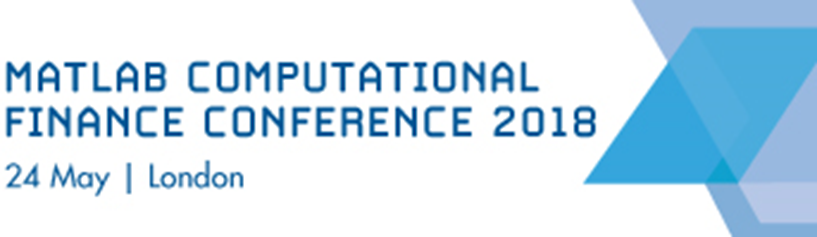

See Also: magic

function a = findArea(shape,dim1,varargin)

% Copyright 2016 The MathWorks, Inc.
% $Revision: $ $Date:  $

% Check number of input and output arguments
narginchk( 2, 3 )
nargoutchk( 0, 1 )

## Using validateattributes directly

validateattributes( shape, {'char','string'}, {'nonempty'}, mfilename, 'shape', 1 )
validateattributes( dim1, {'numeric'}, {'scalar'}, mfilename, 'dim1', 2 )

if nargin == 3
    dim2 = varargin{1};
    validateattributes( dim2, {'numeric'}, {'scalar'}, mfilename, 'dim2', 3 )
else
    % Default value
    dim2 = 1;
end

## Using input parser

p = inputParser;

addRequired(p,'shape',@(x)validateattributes(x,{'char','string'},{'nonempty'}))
addRequired(p,'dim1',@(x)validateattributes(x,{'numeric'},{'nonempty'}))
addOptional(p,'dim2',1,@(x)validateattributes(x,{'numeric'},{'nonempty'}))

parse(p,shape,dim1,varargin{:})
dim2 = p.Results.dim2;

## Using validatestring

shape = validatestring( shape, { 'circle', 'rectangle' }, mfilename, 'shape', 1  );

## Call the correct algorithm

switch shape
    case 'circle'
        a = pi * dim1.^2;
    case 'rectangle'
        a = dim1 .* dim2;
end

end

Copyright 2018 MathWorks Inc.